# Time-Invariant System Identification Using Adaptive Filters

**Objective: **Performed a comparative system identification performance analysis of Variable-RLS and NLMS adaptive filters on an unknown time-invariant system excited by a white noise input.

**Conclusion: **Overall, the results confirm the expected behavior of adaptive filtering algorithms. For a time-invariant unknown system excited by white noise, both NLMS and variable-RLS successfully identify the system coefficients. However, variable-RLS provides faster convergence and lower MSE because it uses more information about the input signal correlation. NLMS converges more slowly, but it is simpler to implement and requires less computation. Therefore, the choice between both algorithms depends on the design requirement: RLS is preferred for rapid convergence, while NLMS is preferred when implementation simplicity and lower computational cost are more important.

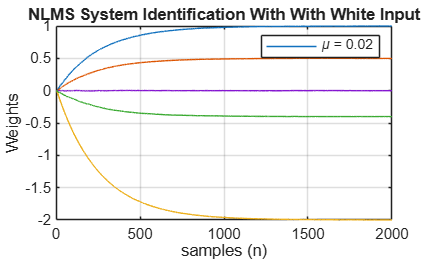

clear; clc;
%% =========================
%% NLMS PARAMETER SETUP
%% =========================
N = 2000;        % Number of samples
NumRuns = 50;    % Number of ensemble runs

h = [1 0.5 -2 0 -0.4].';  % Unknown system

M = length(h);  % Adaptive filter length
mu = 0.02;      % NLMS step size
delta_Nlms = 0.05;  % NLMS Regularization term

% Initialization parameter
delta_Rls = 0.0005;

% Forgetting factor initialization
lamda_init = 0.99;
lamda_min = 0.95;
lamda_max = 1.0;
%% ==============================
%% INITIALIZE ENSEMBLE VARIABLES
%% ==============================
e_ensemble_rls = zeros(N,1);
rls_weights_ensemble = zeros(M,N+1);

e_ensemble_nlms = zeros(N,1);
nWlms_ensemble = zeros(M,N+1);

%% ================
%% NLMS ALGORITHM
%% ================
for i = 1:NumRuns

    % Generate zero-mean white noise input
    u = randn(N,1);

    % Generate zero-mean measurement noise with variance 0.01
    v = sqrt(0.01)*randn(N,1);

    % Desired signal
    d = filter(h,1,u) + v;

    % Initialize NLMS weight history and error vector
    nWlms = zeros(M,N+1);
    nlmsError = zeros(N,1);

    % Initialize the RLS parameters
    rls_weights = zeros(M,N+1);
    uvector = zeros(M,1);
    xi = zeros(N,1);

    P = (1/delta_Rls)*eye(M);
    I = eye(M);

    lamda = lamda_init;

    g = zeros(M,N+1);
    s = zeros(M,M);

    % Update weights according to the NLMS algorithm
    for ii = M:N

        % Input vector: [u(n) u(n-1) ... u(n-M+1)]'
        uVector = u(ii:-1:ii-M+1);

        % NLMS error
        nlmsError(ii) = d(ii) - nWlms(:,ii)' * uVector;

        % Input power
        uPower = uVector' * uVector;

        % NLMS weight update
        nWlms(:,ii+1) = nWlms(:,ii) + ...
            (mu/(delta_Nlms + uPower)) * uVector * nlmsError(ii);

    end

    % Update weights according to the RLS algorithm
    for j = 1:N

        % Input vector
        uvector = [u(j); uvector(1:M-1)];

        % RLS gain vector
        pi_vec = P * uvector;
        k_vec = pi_vec / (lamda + uvector' * pi_vec);

        % Error
        xi(j) = d(j) - rls_weights(:,j)' * uvector;

        % RLS weight update
        rls_weights(:,j+1) = rls_weights(:,j) + k_vec * xi(j);

        % Inverse correlation matrix update
        P = (1/lamda) * (P - k_vec * uvector' * P);

        % Variable forgetting factor update
        lamda = lamda + delta_Rls * (g(:,j)' * uvector * xi(j));

        % Truncation of the forgetting factor
        if lamda_min < lamda && lamda < lamda_max

            s = (1/lamda) * (I - k_vec * uvector') * s * ...
                (I - uvector * k_vec') + ...
                (1/lamda) * ((k_vec * k_vec') - P);

            g(:,j+1) = (I - k_vec * uvector') * g(:,j) + ...
                s * uvector * xi(j);

        else

            lamda = min(max(lamda,lamda_min),lamda_max);

            s = zeros(M,M);
            g(:,j+1) = zeros(M,1);

        end
    end

    % Update ensemble averages

    e_ensemble_nlms = e_ensemble_nlms + nlmsError.^2;
    nWlms_ensemble = nWlms_ensemble + nWlms;

    e_ensemble_rls = e_ensemble_rls + xi.^2;
    rls_weights_ensemble = rls_weights_ensemble + rls_weights;

end

%% =========================
%% AVERAGE ENSEMBLE RESULTS
%% =========================
e_ensemble_nlms = e_ensemble_nlms / NumRuns;
nWlms_ensemble = nWlms_ensemble / NumRuns;

e_ensemble_rls = e_ensemble_rls / NumRuns;
rls_weights_ensemble = rls_weights_ensemble / NumRuns;

%% ==================================================
%% PLOT WEIGHT CONVERGENCE & ENSEMBLE AVERAGED ERRORS
%% ==================================================
figure;
plot(0:N, nWlms_ensemble.');
grid on;
title('NLMS System Identification With With White Input');
xlabel('samples (n)'); ylabel('Weights');
legend(['\mu = ' num2str(mu)])

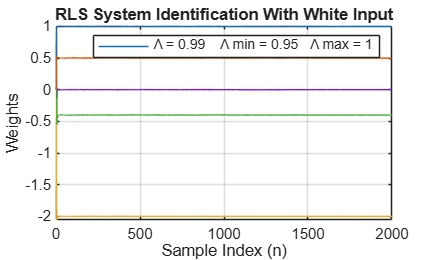


figure;
plot(0:N, rls_weights_ensemble.');
grid on;
title('RLS System Identification With White Input');
xlabel('Sample Index (n)'); ylabel('Weights');
figure;
plot(0:N, rls_weights_ensemble.');
grid on;
title('RLS System Identification With Coloured Inputs');
xlabel('Sample Index (n)'); ylabel('Weights');
legend(['\Lambda = ' num2str(lamda_init) , '    ' ,  ...
        '\Lambda min = ' num2str(lamda_min), '   ' , ...
        '\Lambda max = ' num2str(lamda_max)])


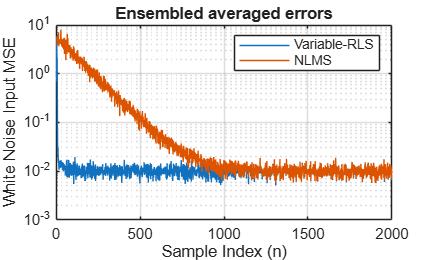

figure;
semilogy(1:N, e_ensemble_rls, 1:N, e_ensemble_nlms);
grid on;
xlim([0, N]);
title('Ensembled averaged errors');
xlabel('Sample Index (n)'); ylabel('White Noise Input MSE');
legend('Variable-RLS', 'NLMS');